LTI systems

Before analysing a signal $x(n)$ the signal is often preprocessed with different transformations $T$ on the input signal $x(n)$ yielding a transformed signal $y(n)=T\{x(n)\}$.The goal of these transformations is to keep all important information of the original signal while getting rid of all unnecessary information (e.g. noise). LTI systems are an important class of transformations for that. 

In this Live Script you will learn which common operations on signals are LTI systems and which not.

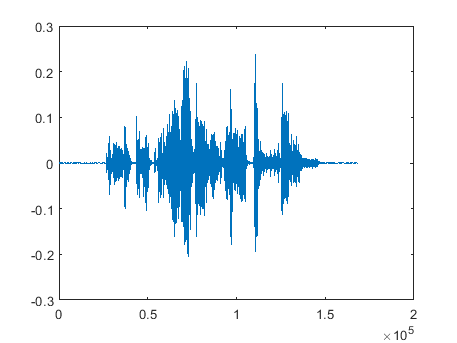

fs=41000;  % sampling rate
audio=audioread("secret-number.mp3");
s=audio(60000:size(audio,1),1);
sound(s,fs);
plot(s)

Now, let's do some simple transformations to the signal $s$ to see what happens to the signal:

- Multiplication with a constant: $y(n) = a*s(n)$

Try different values of $a$ in the range -2.0..2.0. 

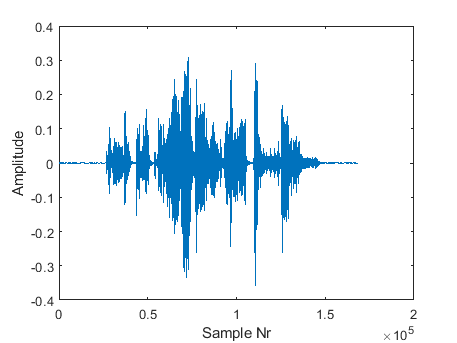

a = -1.5;
y = a.*s;
sound(y,fs);
plot(y)
xlabel("Sample Nr");
ylabel("Amplitude");

- Let's try some other simple operations on $s(n)$

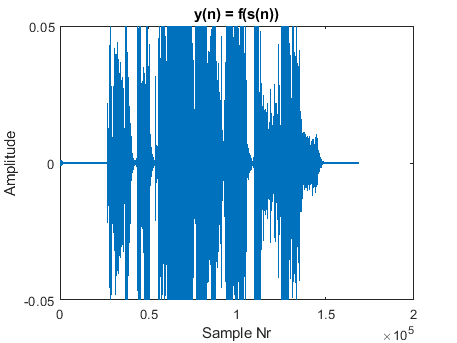


y = max(min(s,0.05),-0.05);

% original signal
sound(s,fs);
pause(5);
% transformed signal
sound(y,fs);
plot(y);
xlabel("Sample Nr");
ylabel("Amplitude");
title("y(n) = f(s(n))");

Now, let's combine two signals:

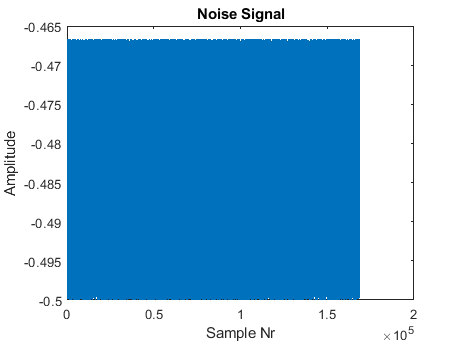


% some white noise
n = 0.1*rand(size(s,1),1)/3-0.5;
sound(n,fs);
plot(n);
xlabel("Sample Nr");
ylabel("Amplitude");
title("Noise Signal");
pause(5);

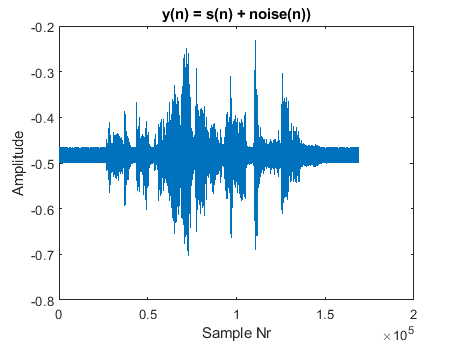


% original signal with noise
x = s + n;
sound(x,fs);
plot(x);
xlabel("Sample Nr");
ylabel("Amplitude");
title("y(n) = s(n) + noise(n))");

Now let's combine different samples of this signal:

- Mean value $y(n) = \frac{x(n) + x(n-1)+x(n-2)}{3}$

% x(n-1)
xminus1= [x(2:size(x));0];
% x(n-2)
xminus2= [xminus1(2:size(x));0];
% mean value
y = (x + xminus1 + xminus2)/3;

% original signal
sound(x,fs);
clear figure;
plot(x(7950:8000),'b');
xlabel("Sample Nr");
ylabel("Amplitude");
title("$y(n)=\frac{x(n)+x(n-1)+x(n-2)}{3}$",Interpreter="latex");
hold;

Current plot held


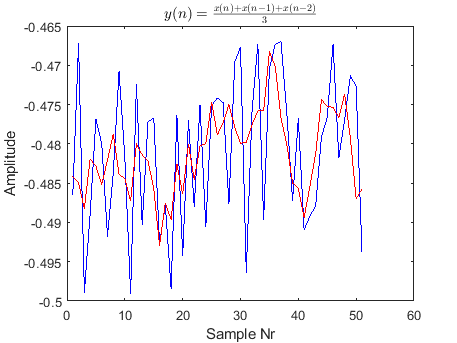

pause(5);
% transformed signal
sound(y,fs);
plot(y(7950:8000),'r');
hold off;

- Median value $y(n) = median(x(n),x(n-1),x(n-2))$

% x(n-1)
xminus1= [x(2:size(x));0];
% x(n-2)
xminus2= [xminus1(2:size(x));0];
% mean value
y = median([x';xminus1';xminus2'],1);
% original signal
sound(x,fs);
clear figure;
plot(x(7950:8000),'b');
xlabel("Sample Nr");
ylabel("Amplitude");
title("$y(n) = median(x(n),x(n-1),x(n-2))$",Interpreter="latex");
hold;

Current plot held


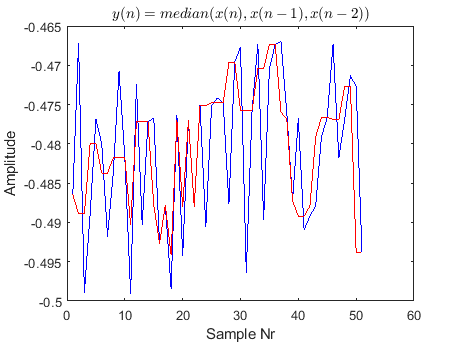

pause(5);
% transformed signal
sound(y,fs);
plot(y(7950:8000),'r');
hold off;

- Difference value $y(n) = \frac{x(n) - x(n-1)}{2}$


% difference value
y = (x - xminus1)/2;

% original signal
sound(x,fs);
clear figure;
plot(x(7950:8000),'b');
xlabel("Sample Nr");
ylabel("Amplitude");
title("$y(n) = \frac{x(n) - x(n-1)}{2}$",Interpreter="latex");
hold;

Current plot held


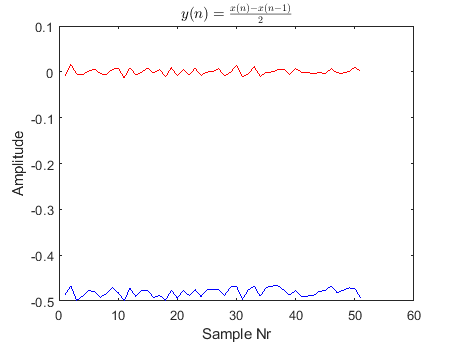

pause(5);
% transformed signal
sound(y,fs);
plot(y(7950:8000),'r');
hold off;

- Moving average FIR filter of order p $y(n)=\frac{x(n)+x(n-1)+x(n-2)+ ... + x(n-p)}{p+1}$

filterorder = 21;
b = (1/filterorder)*ones(1,filterorder);
a = 1;

y = filter(b,a,x);
sound(x,fs);
clear figure;
plot(x(7950:8000),'b');
xlabel("Sample Nr");
ylabel("Amplitude");
title("$y(n)=\frac{x(n)+x(n-1)+x(n-2)+ ... + x(n-p)}{p+1}$",Interpreter="latex");
hold;

Current plot held


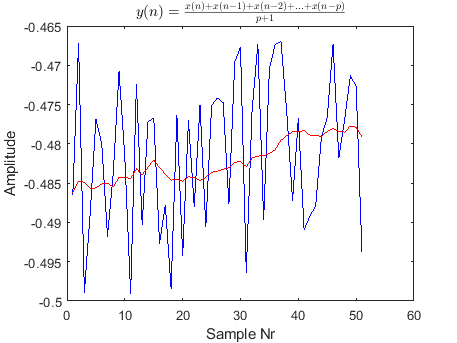

plot(y(7950:8000),'r');
hold off;
pause(5);

sound(y,fs);


